clear all;
close all;

% Load best hyperparameters from Bayesian Optimization
fprintf('Loading best hyperparameters from "Data/best_hyperparameters.mat"...\n');

Loading best hyperparameters from "Data/best_hyperparameters.mat"...


load('../Data/best_hyperparameters.mat', 'bestParams');
fprintf('Best hyperparameters loaded successfully.\n');

Best hyperparameters loaded successfully.




% Load preprocessed data for testing
fprintf('Loading preprocessed data from "Data/preprocessed_data.mat"...\n');

Loading preprocessed data from "Data/preprocessed_data.mat"...


load('../Data/preprocessed_data.mat', 'trainingInputs', 'trainingTargets');
fprintf('preprocessed data (training data) loaded successfully.\n');

preprocessed data (training data) loaded successfully.


disp(bestParams)

    learningRate    momentum    numLayers    numNeurons    epochs    activationFunction    performFcn    trainingFunction
    ____________    ________    _________    __________    ______    __________________    __________    ________________

      0.018579      0.78555         1            40          18            logsig             mse            trainlm     




% Configure the network with the best hyperparameters
fprintf('Configuring neural network with best hyperparameters...\n');

Configuring neural network with best hyperparameters...


bestHiddenLayerSize = repmat(bestParams.numNeurons, 1, bestParams.numLayers);  % Set number of layers and neurons
net = feedforwardnet(bestHiddenLayerSize);  % Initialize network with specified hidden layers

% Set training parameters
net.trainFcn = char(bestParams.trainingFunction);
net.performFcn = char(bestParams.performFcn);
net.trainParam.lr = bestParams.learningRate;
net.trainParam.mc = bestParams.momentum;
net.trainParam.epochs = bestParams.epochs;
net.divideFcn = 'dividetrain';  % Use all data without further internal split

% Set activation function for each layer
for layer = 1:bestParams.numLayers
    net.layers{layer}.transferFcn = char(bestParams.activationFunction);
end

Train the network on the entire training dataset

fprintf('Training the neural network with best hyperparameters...\n');

Training the neural network with best hyperparameters...


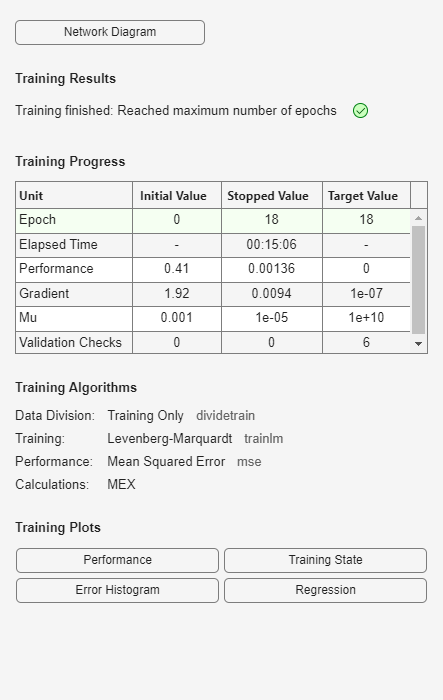

[net, tr] = train(net, trainingInputs, trainingTargets);

fprintf('Training completed.\n');

Training completed.




% save the plots which comes in the UI after training
% Save generated plots after training
fprintf('Saving generated plots...\n');

Saving generated plots...


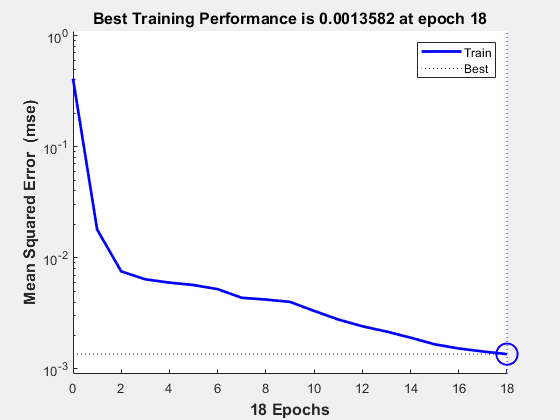


% Performance Plot
if isfield(tr, 'perf')
    figure, plotperform(tr);  % Generate the performance plot
    exportgraphics(gcf, '../outputs/performance_plot_best_observed.png', 'Resolution', 300);  % Save performance plot with high resolution
%    close(gcf);  % Close the figure after saving
end

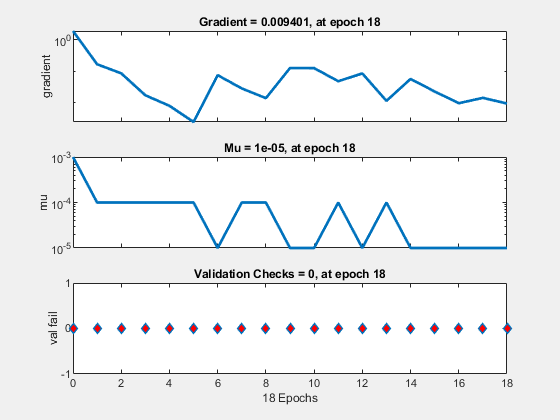


% Training State Plot
if isfield(tr, 'states')
    figure, plottrainstate(tr);  % Generate the training state plot
    exportgraphics(gcf, '../outputs/training_state_plot_best_observed.png', 'Resolution', 300);  % Save training state plot with high resolution
 %   close(gcf);
end


fprintf('All plots saved successfully.\n');

All plots saved successfully.




% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/training_progress_best_observed.png"...\n');

Saving training progress plot to "../outputs/training_progress_best_observed.png"...


figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/training_progress_best_observed.png', 'Resolution', 300);
close(gcf);  % Close the figure after saving
fprintf('Training progress plot saved successfully.\n');

Training progress plot saved successfully.



% Save the trained network and training record
fprintf('Saving trained model to "Data/final_model.mat"...\n');

Saving trained model to "Data/final_model.mat"...


save('../Data/final_model.mat', 'net', 'tr');
fprintf('Trained model saved successfully.\n');

Trained model saved successfully.





% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/training_progress.png"...\n');

Saving training progress plot to "../outputs/training_progress.png"...


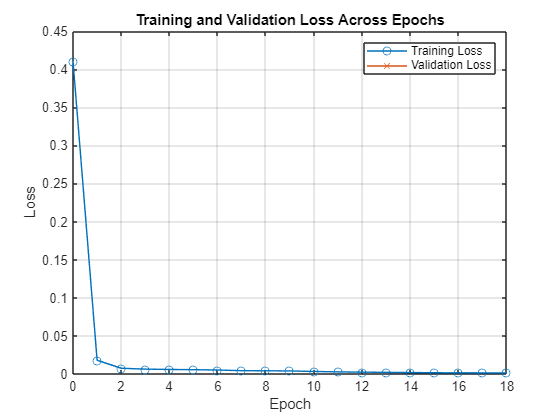

figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/training_progress.png', 'Resolution', 300);


fprintf('Training progress plot saved successfully as PNG.\n');

Training progress plot saved successfully as PNG.
